fov = 100e-3

fov = 0.1000

x = linspace(0,fov,1000)-(fov)/2

x =    -0.0500   -0.0499   -0.0498   -0.0497   -0.0496   -0.0495   -0.0494   -0.0493   -0.0492   -0.0491   -0.0490   -0.0489   -0.0488   -0.0487   -0.0486   -0.0485   -0.0484   -0.0483   -0.0482   -0.0481   -0.0480   -0.0479   -0.0478   -0.0477   -0.0476   -0.0475   -0.0474   -0.0473   -0.0472   -0.0471   -0.0470   -0.0469   -0.0468   -0.0467   -0.0466   -0.0465   -0.0464   -0.0463   -0.0462   -0.0461   -0.0460   -0.0459   -0.0458   -0.0457   -0.0456   -0.0455   -0.0454   -0.0453   -0.0452   -0.0451



L = 3e-3

L = 0.0030

wavelength = 1.5e-3

wavelength = 0.0015

z = 1e-2

z = 0.0100

amp = 1

amp = 1


pressure =  p(L,x,wavelength,z,amp)

pressure =   -0.0000 - 0.0000i  -0.0011 - 0.0011i  -0.0022 - 0.0022i  -0.0033 - 0.0033i  -0.0044 - 0.0044i  -0.0054 - 0.0054i  -0.0065 - 0.0065i  -0.0075 - 0.0075i  -0.0085 - 0.0085i  -0.0095 - 0.0095i  -0.0105 - 0.0105i  -0.0114 - 0.0114i  -0.0122 - 0.0122i  -0.0131 - 0.0131i  -0.0138 - 0.0138i  -0.0146 - 0.0146i  -0.0152 - 0.0152i  -0.0158 - 0.0158i  -0.0164 - 0.0164i  -0.0169 - 0.0169i  -0.0173 - 0.0173i  -0.0176 - 0.0176i  -0.0179 - 0.0179i  -0.0181 - 0.0181i  -0.0183 - 0.0183i  -0.0184 - 0.0184i  -0.0184 - 0.0184i  -0.0183 - 0.0183i  -0.0181 - 0.0181i  -0.0179 - 0.0179i  -0.0176 - 0.0176i  -0.0173 - 0.0173i  -0.0168 - 0.0168i  -0.0163 - 0.0163i  -0.0158 - 0.0158i  -0.0151 - 0.0151i  -0.0144 - 0.0144i  -0.0137 - 0.0137i  -0.0129 - 0.0129i  -0.0120 - 0.0120i  -0.0111 - 0.0111i  -0.0101 - 0.0101i  -0.0091 - 0.0091i  -0.0081 - 0.0081i  -0.0070 - 0.0070i  -0.0059 - 0.0059i  -0.0047 - 0.0047i  -0.0036 - 0.0036i  -0.0024 - 0.0024i  -0.0012 - 0.0012i


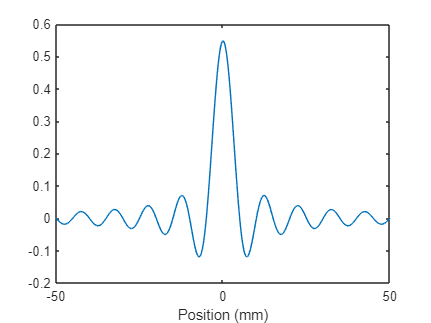

plot(x*1e3,real(pressure))
xlabel('Position (mm)')

function pressure = p(L,x,wavelength,z,amp)
pressure = L*exp(1i*pi/4)*sqrt(amp/(wavelength*z))*sinc((L*x)/(wavelength*z));
end
